初始化数据读取

clc;
clear;

% 读取processed_data.csv数据
data = readtable('processed_data.csv');
lat = data.lat;
lon = data.lon;
alt = data.alt;
acc_x = data.acc_x;
acc_y = data.acc_y;
acc_z = data.acc_z;

绘制高度直方图

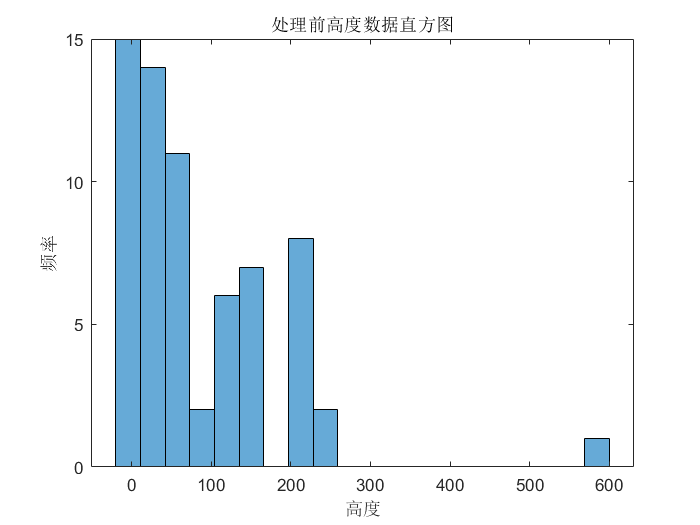

% 绘制高度数据的直方图
figure;
histogram(alt, 20); % 使用20个bin绘制直方图
xlabel('高度');
ylabel('频率');
title('处理前高度数据直方图');

% 数据预处理：Z-Score 方法剔除异常值

% z_threshold = 3; % Z-Score阈值，通常为3
% z_scores_lat = (lat - mean(lat)) / std(lat);
% z_scores_lon = (lon - mean(lon)) / std(lon);
% z_scores_alt = (alt - mean(alt)) / std(alt);
% 
% valid_indices = abs(z_scores_lat) < z_threshold & abs(z_scores_lon) < z_threshold & abs(z_scores_alt) < z_threshold;
% lat = lat(valid_indices);
% lon = lon(valid_indices);
% alt = alt(valid_indices);
% acc_x = acc_x(valid_indices);
% acc_y = acc_y(valid_indices);
% acc_z = acc_z(valid_indices);
% 
%  b = [lat lon alt]



%使用IQR方法剔除异常值

Q1_lat = quantile(lat, 0.25);
Q3_lat = quantile(lat, 0.75);
IQR_lat = Q3_lat - Q1_lat;
lower_bound_lat = Q1_lat - 1.5 * IQR_lat;
upper_bound_lat = Q3_lat + 1.5 * IQR_lat;

Q1_lon = quantile(lon, 0.25);
Q3_lon = quantile(lon, 0.75);
IQR_lon = Q3_lon - Q1_lon;
lower_bound_lon = Q1_lon - 1.5 * IQR_lon;
upper_bound_lon = Q3_lon + 1.5 * IQR_lon;

Q1_alt = quantile(alt, 0.25);
Q3_alt = quantile(alt, 0.75);
IQR_alt = Q3_alt - Q1_alt;
lower_bound_alt = Q1_alt - 1.5 * IQR_alt;
upper_bound_alt = Q3_alt + 1.5 * IQR_alt;

valid_indices = (lat >= lower_bound_lat & lat <= upper_bound_lat) & ...
                (lon >= lower_bound_lon & lon <= upper_bound_lon) & ...
                (alt >= lower_bound_alt & alt <= upper_bound_alt);

lat = lat(valid_indices);
lon = lon(valid_indices);
alt = alt(valid_indices);
acc_x = acc_x(valid_indices);
acc_y = acc_y(valid_indices);
acc_z = acc_z(valid_indices);



% 绘制高度数据的直方图

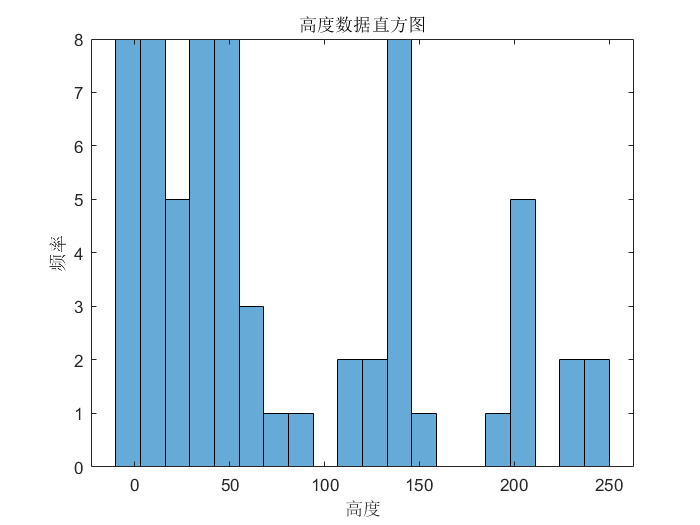

figure;
histogram(alt, 20); % 使用20个bin绘制直方图
xlabel('高度');
ylabel('频率');
title('高度数据直方图');

% 分段平滑处理高度数据

% num_segments = 5;
% segment_length = floor(length(alt) / num_segments);
% smoothed_alt = [];
% 
% for i = 1:num_segments
%     start_idx = (i-1) * segment_length + 1;
%     if i < num_segments
%         end_idx = i * segment_length;
%     else
%         end_idx = length(alt);
%     end
%     
%     segment = alt(start_idx:end_idx);
%     smoothed_segment = smoothdata(segment, 'movmean', 5); % 对每段进行滑动窗口平滑
%     smoothed_alt = [smoothed_alt; smoothed_segment];
% end


%基于绝对值差异的方法：

% med_lat = median(lat);
% med_lon = median(lon);
% med_alt = median(alt);
% 
% MAD_lat = median(abs(lat - med_lat));
% MAD_lon = median(abs(lon - med_lon));
% MAD_alt = median(abs(alt - med_alt));
% 
% threshold = 1; % 可以根据需要调整
% valid_indices = (abs(lat - med_lat) / MAD_lat < threshold) & ...
%                 (abs(lon - med_lon) / MAD_lon < threshold) & ...
%                 (abs(alt - med_alt) / MAD_alt < threshold);
% 
% lat = lat(valid_indices);
% lon = lon(valid_indices);
% alt = alt(valid_indices);
% acc_x = acc_x(valid_indices);
% acc_y = acc_y(valid_indices);
% acc_z = acc_z(valid_indices);




% 数据平滑处理：中值滤波和滑动窗口平滑

curve_x = medfilt1(lat, 5); % 中值滤波
curve_y = medfilt1(lon, 5); % 中值滤波
curve_z = medfilt1(alt, 5); % 中值滤波

curve_x = smoothdata(curve_x, 'movmean', 5); % 滑动窗口平滑
curve_y = smoothdata(curve_y, 'movmean', 5); % 滑动窗口平滑
curve_z = smoothdata(curve_z, 'movmean', 5); % 滑动窗口平滑


% 初始化卡尔曼滤波器参数

dt = 0.1; % 采样时间
A = [1 0 0 dt 0 0; 0 1 0 0 dt 0; 0 0 1 0 0 dt; 0 0 0 1 0 0; 0 0 0 0 1 0; 0 0 0 0 0 1]; % 状态转移矩阵
B = [0.5*dt^2 0 0; 0 0.5*dt^2 0; 0 0 0.5*dt^2; dt 0 0; 0 dt 0; 0 0 dt]; % 控制输入矩阵
C = [1 0 0 0 0 0; 0 1 0 0 0 0; 0 0 1 0 0 0]; % 观测矩阵

% 初始估计误差协方差矩阵
P = eye(6); % 估计误差协方差
x = [curve_x(1); curve_y(1); curve_z(1); 0; 0; 0]; % 初始状态，包括位置和速度

% 过程噪声协方差矩阵
Q = 0.001 * eye(6); % 调整这个值进行优化

% 观测噪声协方差矩阵
R = 0.01 * eye(3); % 调整这个值进行优化

执行滤波

% 存储滤波结果
numDataPoints = length(curve_x);
x_filtered = zeros(numDataPoints, 6);
x_filtered(1, :) = x';

for i = 2:numDataPoints
    % 状态预测
    u = [acc_x(i); acc_y(i); acc_z(i)]; % 控制输入
    x = A * x + B * u;
    P = A * P * A' + Q;
    
    % 卡尔曼增益
    K = P * C' / (C * P * C' + R);
    
    % 更新状态
    z = [curve_x(i); curve_y(i); curve_z(i)]; % 观测值
    x = x + K * (z - C * x);
    P = (eye(6) - K * C) * P;
    
    % 存储结果
    x_filtered(i, :) = x';
end

图片绘制

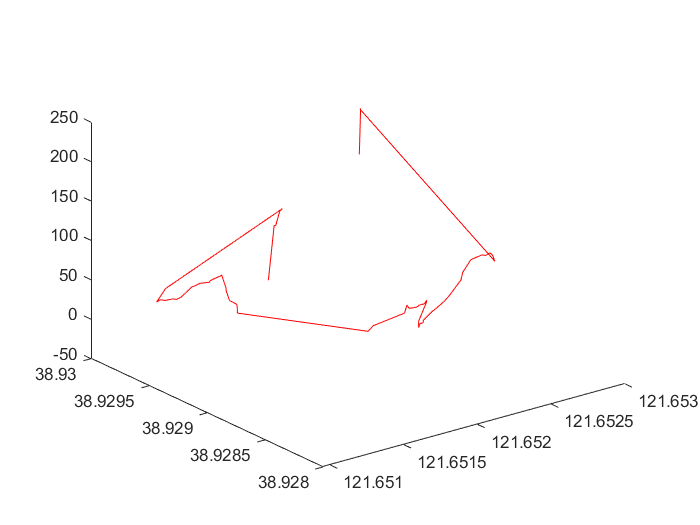

% 绘制原始数据路径（3D）
figure;
plot3(lon, lat, alt, 'r-', 'DisplayName', '原始路径');
% 保存图表
saveas(gcf, 'filtered_path_3D_origin.png');

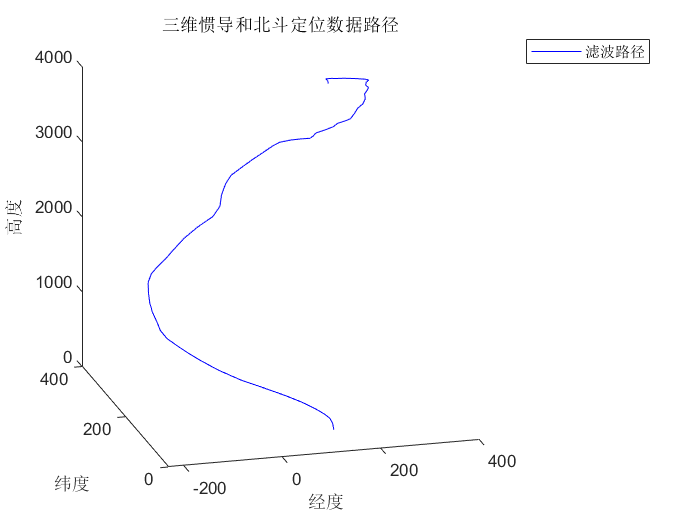


% 绘制滤波后数据路径（3D）
plot3(x_filtered(:, 2), x_filtered(:, 1), x_filtered(:, 3), 'b-', 'DisplayName', '滤波路径');

% 设置图例和标题
legend;
xlabel('经度');
ylabel('纬度');
zlabel('高度');
title('三维惯导和北斗定位数据路径');

% 保存图表
saveas(gcf, 'filtered_path_3D_fliter.png');